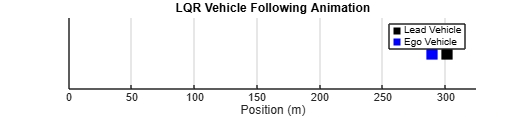

clc; clear;

%% --- Simulation Parameters ---
Ts = 0.1;
N = 300;
minDist = 6;

mu = 0.01;  % Rolling resistance coefficient
g = 9.81;

profile = 1;

%% --- Lead vehicle velocity profile ---
if profile == 1
    t = (0:N-1)' * Ts;
    v_lead = 10 + 2 * sin(2 * pi * 0.1 * t);
elseif profile == 2
    v_lead = zeros(N,1);
    v_lead(1:20) = linspace(0, 10, 20); 
    v_lead(21:60) = 10;
    v_lead(61:80) = linspace(10, 0, 20);
    v_lead(81:end) = 0;
end

x_lead = zeros(N,1);
for k = 2:N
    x_lead(k) = x_lead(k-1) + Ts * v_lead(k-1);
end

%% --- Ego Vehicle Model ---
A = [1 Ts; 0 1];
B = [0; Ts];
C = eye(2);  
E = [0; -mu * g];

%% --- LQR Design ---
Q = diag([2, 100]);  
R = 1;
K = dlqr(A, B, Q, R);

%% --- Desired velocity shaping (nonlinear logic) ---
k_gain = 0.1;
v_bar = 8;
A_gain = 1;
B_gain = 1;

%% --- Initial Conditions ---
x_ego = zeros(2,1);
x_lead0 = 6;
x_lead = x_lead + x_lead0;

ulog = zeros(N,1);
dist = zeros(N,1);
v_ego_log = zeros(N,1);

%% --- Simulation Loop ---
for k = 1:N
    D = x_lead(k) - x_ego(1); 
    v = x_ego(2);    
    vl = v_lead(k);      

    Vd = max(0, min(k_gain * (D - minDist), v_bar));
    Wvl = min(vl, v_bar);

    v_ref = A_gain * Vd + B_gain * Wvl;

    x_ref = [x_lead(k) - minDist; v_ref]; 
    u = -K * (x_ego - x_ref);

    u = min(max(u, -3), 2);

    x_ego = A * x_ego + B * u + E;

    ulog(k) = u;
    dist(k) = x_lead(k) - x_ego(1);
    v_ego_log(k) = x_ego(2);
end

roadLength = max(x_lead) + 20;  
ego_pos = x_lead - dist;      

figure;
hFig = gcf;
hFig.Position(3:4) = [900, 200];
axis([0 roadLength -2 2]);
hold on;
grid on;

lead_plot = plot(0, 0, 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
ego_plot  = plot(0, 0, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
title('LQR Vehicle Following Animation');
xlabel('Position (m)');
yticks([]);
legend('Lead Vehicle', 'Ego Vehicle');

%% Animation loop
for k = 1:5:N
    set(lead_plot, 'XData', x_lead(k));
    set(ego_plot, 'XData', ego_pos(k));
    drawnow;
    pause(0.05);
end

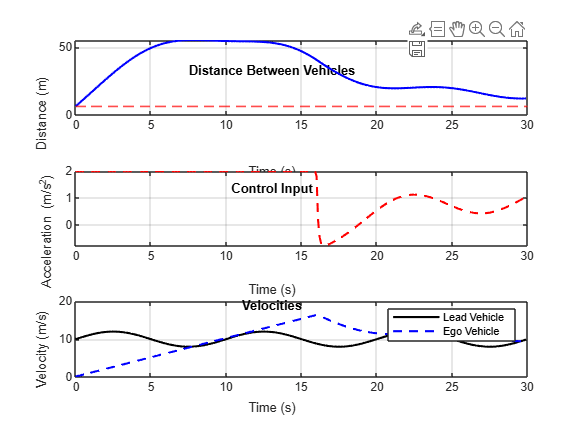


%% --- Plotting ---
t = (0:N-1)*Ts;

figure;
subplot(3,1,1)
plot(t, dist, 'b-', 'LineWidth', 1.5); hold on;
yline(minDist, 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Distance (m)');
title('Distance Between Vehicles'); grid on;

subplot(3,1,2)
plot(t, ulog, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)');
title('Control Input'); grid on;

subplot(3,1,3)
plot(t, v_lead, 'k-', t, v_ego_log, 'b--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Velocity (m/s)');
legend('Lead Vehicle', 'Ego Vehicle');
title('Velocities'); grid on;